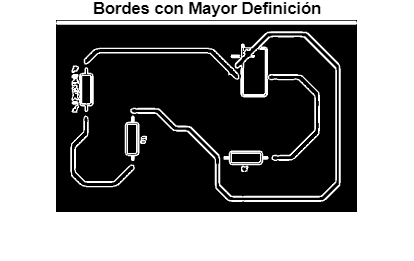

    if evalin('base','exist(''ImagePath'',''var'')') && evalin('base','Value')=='A'
    ImagePath = evalin ('base','ImagePath')
% Cargar la imagen en alta resolución
image = imread(ImagePath);

% Convertir a escala de grises
gray = rgb2gray(image);

% Aplicar filtro Gaussiano con sigma menor para mantener detalles
blurred = imgaussfilt(gray, 1); %    Reducimos el suavizado

% Aplicar detección de bordes con Canny ajustando umbrales
edges = edge(blurred, 'Canny', [0.01, 0.1]); % Detecta más detalles

% Alternativa: Usar filtro Sobel para resaltar más bordes
sobelEdges = edge(blurred, 'Sobel');

% Combinar ambos métodos (Canny + Sobel) para mayor precisión
combinedEdges = edges | sobelEdges;

% Filtrar ruido eliminando regiones pequeñas
filteredEdges = bwareaopen(combinedEdges, 30); % Se reduce menos que antes

% Encontrar contornos y extraer waypoints
[B, L] = bwboundaries(filteredEdges, 'noholes');

% Mostrar los bordes con mayor detalle
figure;
imshow(filteredEdges);
hold on;
title('Bordes con Mayor Definición');

% Extraer y dibujar waypoints
waypoints = [];
for k = 1:length(B)
    boundary = B{k}; % Coordenadas del contorno
    plot(boundary(:,2), boundary(:,1), 'w', 'LineWidth', 0.5); % Dibujar contorno más fino
    
    % Almacenar waypoints
    waypoints = [waypoints; boundary];
end
hold off;


% Guardar los waypoints con mayor definición
save('waypoints_highres.mat', 'waypoints');
assignin('base','waypoints',waypoints)
end